# Running Python with MATLAB

## Call Python from MATLAB

### Option 1: Setup a Python Environment

Check which version of Python is installed and that it is on your MATLAB path. if running on matlab online, a version of Python is already installed on the MathWorks' servers.

py = pyenv % or pyenv()

if py.Version == ""
    disp "Python not installed"
end

If multiple versions of Python are detected or installed on your computer, specify the version of Python you want to run:

pyenv(Version="3.11");

If you downloaded a Python interpreter, but did not register it in the Windows registry, use:

Check to see if your environment is initialized.

py.math.sqrt(42)

Once your Python Environment (pyenv) is initialized, try this:

% Type your python code here



Did your code run? What happened? What do you need to change? What inputs do you have to specify?

% SPOILER ALERT
% hw = py.textwrap.wrap("Hello world!",pyargs('width',int8(2)))

#### Converting Data Types

Some data types you can operate on directly or MATLAB will automatically assign a class such as string or double. Others will appear in your workspace as "py" variables, such as "py.list".

**Two examples:**

If you have a Python dictionary, you can convert it to a MATLAB dictionary using the `dictionary` function. *(since R2024a). *MATLAB converts the Python keys and values to the equivalent type in  MATLAB when possible. If the Python dictionary keys are not all of the  same data type when automatically converted to a MATLAB data type, the  keys are wrapped in cell arrays. The same is true of the Python  dictionary values.  

For example, create a Python dictionary and convert it to a MATLAB  dictionary. In this case, MATLAB converts the keys to strings and the  values to doubles.

dp = py.dict(soup=3.57,bread=2.29,bacon=3.91,salad=5.00);  
dm = dictionary(dp) 

Alternatively, you can convert Python dictionaries to MATLAB structures  using the struct function as long as the Python dictionary keys are  valid MATLAB identifiers. 

sm = struct(dp)

Learn more on our documentation pages dedicated to [using Python dictionaries in MATLAB](https://www.mathworks.com/help/matlab/matlab_external/python-dict-variables.html) and our main documentation hub for [calling Python from MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html?s_tid=CRUX_lftnav).

### Option 2: Use the Python Live Task

Navigate to your toolstrip and select the Live Editor tab. In the Code section, select Task. Search for and select "Run Python Code".

% Python code input
pycode = [...
"math.sqrt(42)",...
"",...
"",...
"## import math as math",...
"##  math.sqrt(42)",...
"## print(math.sqrt(42))",...
"## mm = math.sqrt(42)"...
];

try
    pyrun(pycode)
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    rethrow(ME)
end

% Clear temporary variables from workspace and from Python
clear pycode;

### Export MATLAB as...

In the toolstrip, navigate to Live Editor > Export > Export to...

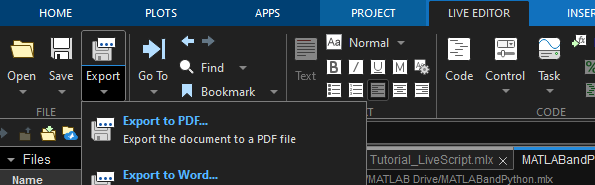

### Compile MATLAB Code as a Standalone Executable or as Python Code

(not available in online version)

In the toolstrip, navigate to Apps > Standalone Application Compiler.

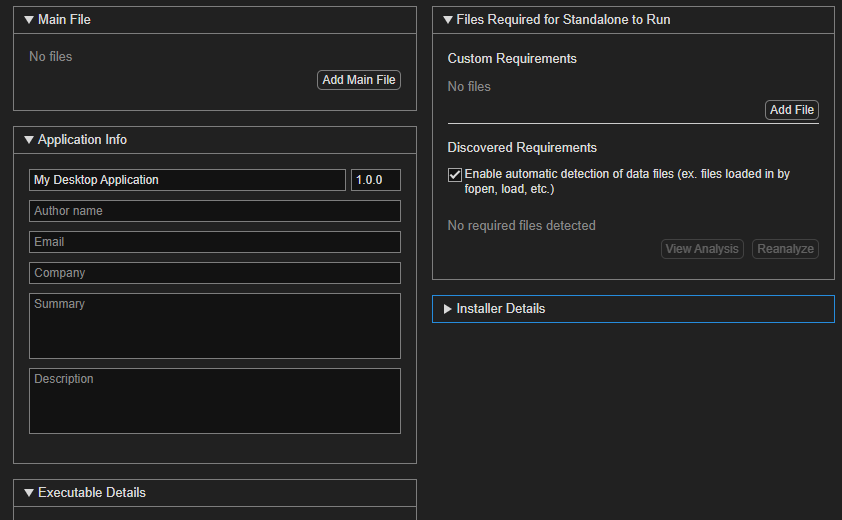

## Call MATLAB from Python

MATLAB Runtime

*© The MathWorks, Inc. 2024*